# **PART 2: Modeling**

clear all
clc

# Exercise 2.1

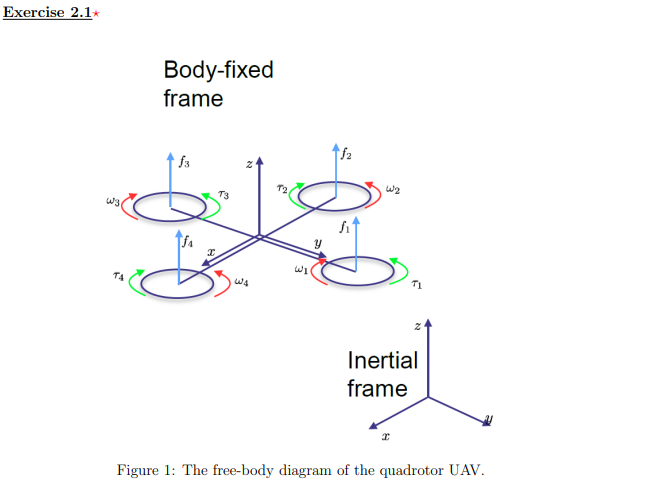

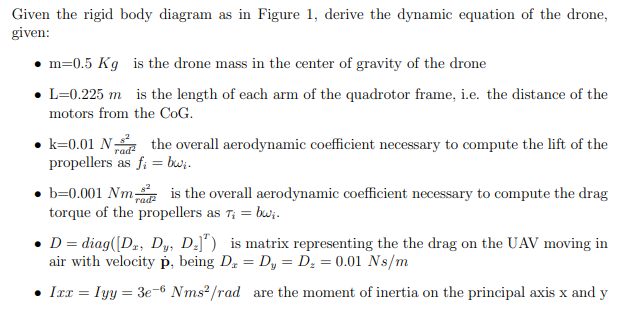

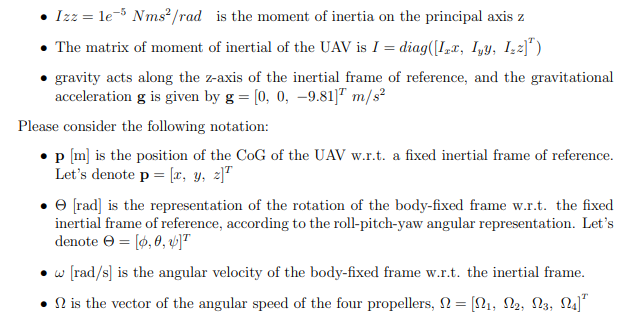

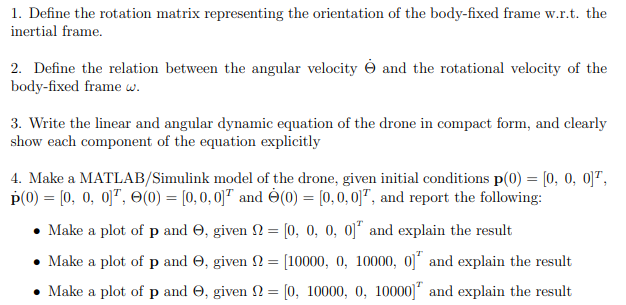

syms x y z phi theta psi theta_dot phi_a
m=0.5    % m=0.5 Kg 

m = 0.5000

L=0.225  %L=0.225 m 

L = 0.2250

k=0.01   %N(s^2/rad^2)

k = 0.0100

b=0.001 %Nm(s^2/rad^2)

b = 1.0000e-03

D=diag([0.01,0.01,0.01]') %Ns/m

D =     0.0100         0         0
         0    0.0100         0
         0         0    0.0100


Ixx=3*exp(-6)   %Nm(s^2/rad)

Ixx = 0.0074

Iyy=3*exp(-6)   %Nm(s^2/rad)

Iyy = 0.0074

Izz=1*exp(-5)   %Nm(s^2/rad)

Izz = 0.0067

I=diag([Ixx,Iyy,Izz]')

I =     0.0074         0         0
         0    0.0074         0
         0         0    0.0067


g=[0,0,-9.81]'  %m/s

g =          0
         0
   -9.8100


%p_m=[x,y,z]'
%Theta=[phi,theta,psi]'

%1.
Rotation=[cos(psi)*cos(theta) cos(psi)*sin(theta)*sin(phi)-sin(psi)*cos(theta) cos(psi)*sin(theta)*cos(phi)+sin(psi)*sin(theta);...
          sin(psi)*cos(theta) sin(psi)*sin(theta)*sin(phi)-cos(psi)*cos(theta) sin(psi)*sin(theta)*cos(phi)+cos(psi)*sin(theta);...
          -sin(theta) cos(theta)*sin(phi) cos(theta)*cos(phi)]

$$Rotation = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{2} & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\sigma_{1} & \sin\left(\psi \right)\,\sin\left(\theta \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \sigma_{1} & \sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\sigma_{2} & \cos\left(\psi \right)\,\sin\left(\theta \right)+\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sigma_{2}=\cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}$$

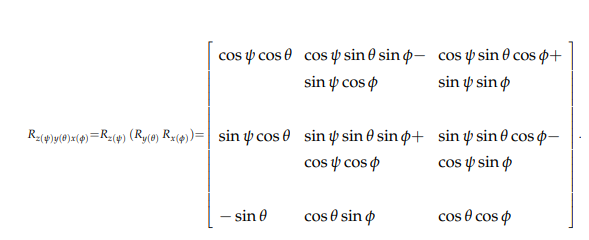

%2.
w=[1 0 -sin(theta); 0 cos(phi) cos(theta)*sin(phi); 0 -sin(phi) cos(theta)*cos(phi)]%*theta_dot

$$w = \left(\begin{array}{ccc} 1 & 0 & -\sin\left(\theta \right)\\ 0 & \cos\left(\varphi \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right)\\ 0 & -\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

%3. Slide page 58 modeling

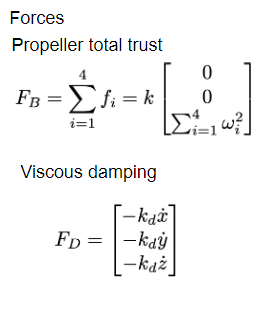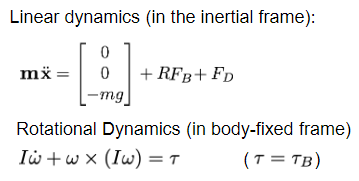

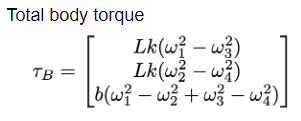

%4.
syms a b c d
p_0=[0 0 0]';
dp_0=[0 0 0]';
theta_0=[0 0 0]';
dtheta_0=[0 0 0]';


$$x = a+\psi +\theta$$

$$ans = b+c+d$$

# Exercise 2.2

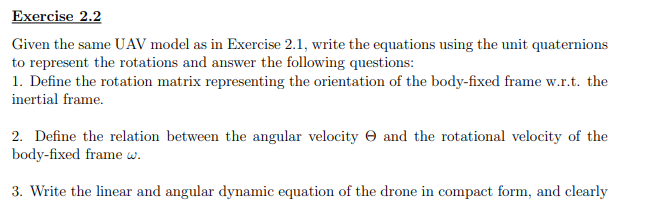

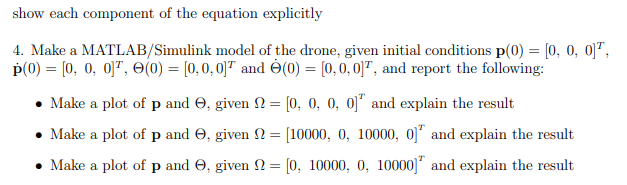

# Exercise 2.3